mu=5.6;Lz=1.0;Lx=24.0;
Nz=30;Nx=100;N=Nz*Nx;
[dz,z]=ched(Nz);dz=(2/Lz)*dz;z=(1+z)/2;
[dx,x]=ched(Nx);dx=(2/Lx)*dx;x=(Lx/2)*x;
Iz=speye(Nz);Ix=speye(Nx);I=speye(N);%O=sparse(N,N);
Dz=kron(dz,Ix);Dx=kron(Iz,dx);
Dzz=kron(dz^2,Ix);Dxx=kron(Iz,dx^2);
[zz,xx]=meshgrid(z,x);
Z=zz(:);X=xx(:);
z0=find(Z==0);
z1=find(Z==1);
xb=find(abs(X)==Lx/2);
bd=union(union(z0,z1),xb);
%initialization
psi=4*Z.*tanh(X);phi=mu*(1-Z);
seed=[psi;phi];scale=length(seed);sol=zeros(scale,1);
fz=1-Z.^3;fpz=-3*Z.^2;
tol=1e-5;tau=0.1;
k=0;kmax=9;eps=1e-6;
tic
while k<kmax
    %computing b
    R1=phi.^2.*psi+fz.*(-Z.*psi+(Dxx*psi)+fpz.*(Dz*psi)+fz.*(Dzz*psi));
    R2=-2*phi.*psi.^2+(Dxx*phi)+fz.*(Dzz*phi);
    R1(z1)=fpz(z1).*(Dz(z1,:)*psi)+(Dxx(z1,:)*psi)-psi(z1);
    R1(z0)=psi(z0);
    R1(xb)=Dx(xb,:)*psi;
    R2(z1)=phi(z1);
    R2(z0)=phi(z0)-mu;
    R2(xb)=Dx(xb,:)*phi;
    b=-[R1;R2];
    %computing A
    A11=diag(-Z.*fz+phi.^2)+fz.*Dxx+fz.^2.*Dzz+fz.*fpz.*Dz;
    A12=diag(2*phi.*psi);
    A21=diag(-4*psi.*phi);
    A22=diag(-2*psi.^2)+Dxx+fz.*Dzz;
    A11(z0,:)=I(z0,:);A11(z1,:)=fpz(z1).*Dz(z1,:)+Dxx(z1,:)-I(z1,:);
    A11(xb,:)=Dx(xb,:);
    A12(bd,:)=0;
    A21(bd,:)=0;
    A22(z0,:)=I(z0,:);A22(z1,:)=I(z1,:);
    A22(xb,:)=Dx(xb,:);
    A=[A11,A12;A21,A22];
    sol=A\b;%solve linear systems
    solrms = sqrt(sum(sol.^2)/scale)
    seed=seed+sol;
    reseed=reshape(seed,[],2);
    psi=reseed(:,1);
    phi=reseed(:,2);
    if solrms < eps
        break;
    else
        k=k+1;
    end
end
toc

时间已过 43.298088 秒。


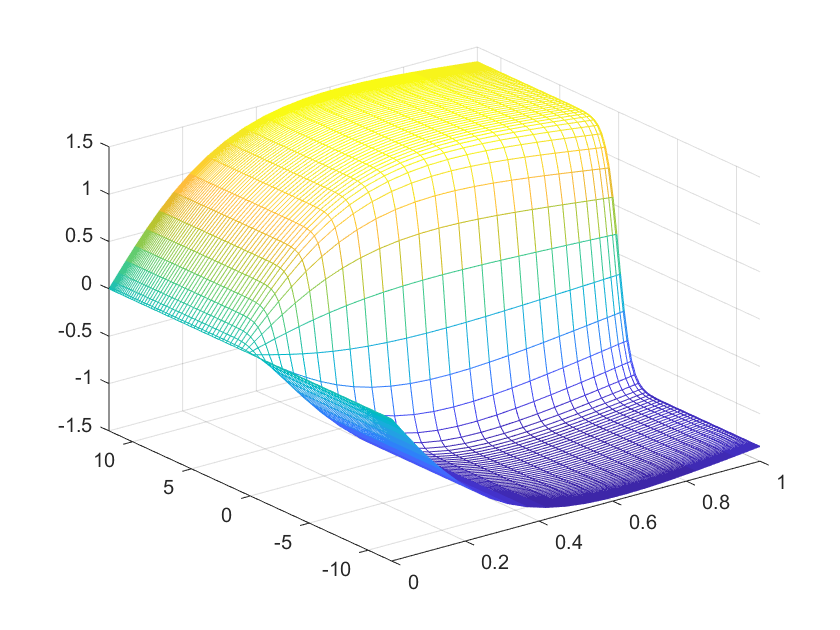

mesh(zz,xx,reshape(psi,[Nx,Nz]))